velocity = '0.1 m/s';
data = d;
t = data(:,1);
r = data(:,3);
first = find(r>1e-4,1)

first = 39

time = t(first:end)-t(first)+1;
radius = r(first:end);

% Transformation to logarithmic scale
log_t = log(time);
log_h = log(radius);
% Linear fit of data in logarithmic scale
fit = polyfit(log_t,log_h,1)

fit = 1.0e+03 *

    2.2685   -0.0087


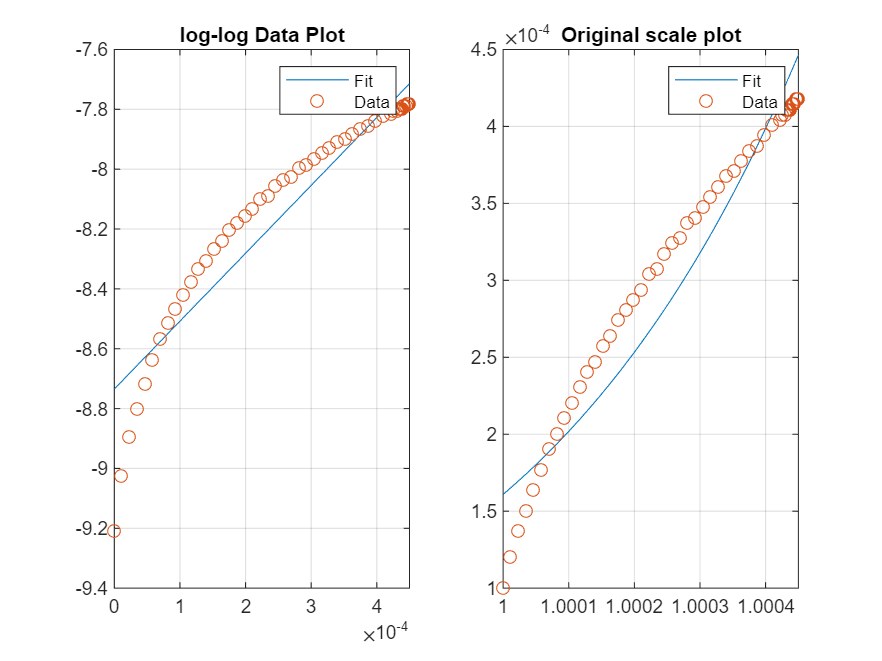

% Generate linear fit curve in the logarithmic scale
xVec = linspace(log_t(1),log_t(end),100);
log_h_fit = polyval(fit,xVec);
% Plot logarithmic data and fit
subplot(1,2,1);
plot(xVec,log_h_fit,log_t,log_h,'o');
grid on;
legend('Fit','Data')
title('log-log Data Plot')
% Convert from logarithmic scale to linear scale
m = fit(1);
b = fit(2);
h_fit = t.^m*exp(b);
% Plot linear scale
subplot(1,2,2)
plot(time,time.^fit(1)*exp(fit(2)),time,radius,'o');
grid on;
legend('Fit','Data');
title('Original scale plot')